clear
syms x y
L1=4*x+3*y-12

$$L1 = 4\,x+3\,y-12$$

hold on
ezplot(L1,[-2 8])
grid
L1=L1/12

$$L1 = \frac{x}{3}+\frac{y}{4}-1$$

[xa ya]=solve(L1,y==0);A=[xa ya]

$$A = \left(\begin{array}{cc} 3 & 0 \end{array}\right)$$

[xb yb]=solve(L1,x==0);B=[xb yb]

$$B = \left(\begin{array}{cc} 0 & 4 \end{array}\right)$$

plot(A(1),A(2),'ro')
plot(B(1),B(2),'go')
kab=sym(-4/3),kcd=kab

$$kab = -\frac{4}{3}$$

$$kcd = -\frac{4}{3}$$

kbc=-1/kab,kad=kbc

$$kbc = \frac{3}{4}$$

$$kad = \frac{3}{4}$$

syms x y x1 y1 k
L=y-y1==k*(x-x1) 

$$L = y-y_{1}=k\,\left(x-x_{1}\right)$$

Lbc=simplify(subs(L,[k x1 y1],[kbc B]))

$$Lbc = y-4=\frac{3\,x}{4}$$

Lad=simplify(subs(L,[k x1 y1],[kbc A]))

$$Lad = 3\,x=4\,y+9$$

ezplot(Lbc)
ezplot(Lad)
syms alpha k1 k2
eq1=tan(alpha)==abs((k2-k1)/(1+k1*k2))  

$$eq1 = \tan\left(\alpha \right)=\frac{\left|k_{1}-k_{2}\right|}{\left|k_{1}\,k_{2}+1\right|}$$

eq2=subs(eq1,[alpha k1],[pi/4 kab])

$$eq2 = 1=\frac{\left|k_{2}+\frac{4}{3}\right|}{\left|\frac{4\,k_{2}}{3}-1\right|}$$

k2=solve(eq2,k2)

$$k2 = \left(\begin{array}{c} -\frac{1}{7}\\ 7 \end{array}\right)$$

kbd=k2(1)

$$kbd = -\frac{1}{7}$$

kac=k2(2)

$$kac = 7$$

Lbd=simplify(subs(L,[k x1 y1],[kbd B]))

$$Lbd = y-4=-\frac{x}{7}$$

Lac=simplify(subs(L,[k x1 y1],[kac A]))

$$Lac = 7\,x=y+21$$

ezplot(Lbd)
ezplot(Lac)
[xc yc]=solve(Lbc,Lac),C=[xc yc]

$$xc = 4$$

$$yc = 7$$

$$C = \left(\begin{array}{cc} 4 & 7 \end{array}\right)$$

[xd yd]=solve(Lad,Lbd),D=[xd yd]

$$xd = 7$$

$$yd = 3$$

$$D = \left(\begin{array}{cc} 7 & 3 \end{array}\right)$$

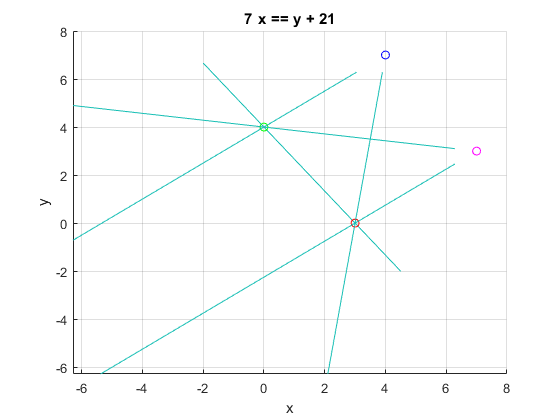

plot(C(1),C(2),'bo')
plot(D(1),D(2),'mo')

Lcd=line2p(C,D)

$$Lcd = 4\,x+3\,y=37$$

% Вариант 2
syms xc yc xd yd
C=[xc yc]

$$C = \left(\begin{array}{cc} \mathrm{xc} & \mathrm{yc} \end{array}\right)$$

D=[xd yd]

$$D = \left(\begin{array}{cc} \mathrm{xd} & \mathrm{yd} \end{array}\right)$$

Lbc1=subs(Lbc,[x y],C)

$$Lbc1 = \mathrm{yc}-4=\frac{3\,\mathrm{xc}}{4}$$

Lad1=subs(Lad,[x y],D)

$$Lad1 = 3\,\mathrm{xd}=4\,\mathrm{yd}+9$$

AB=seglen(A,B)

$$AB = 5$$

BC=seglen(B,C)

$$BC = \sqrt{{\left(\mathrm{yc}-4\right)}^{2}+{\mathrm{xc}}^{2}}$$

AD=seglen(A,D)

$$AD = \sqrt{{\left(\mathrm{xd}-3\right)}^{2}+{\mathrm{yd}}^{2}}$$

[xc yc]=solve(Lbc1,BC==AB);C1=[xc(1) yc(1)],C2=[xc(2) yc(2)]

$$C1 = \left(\begin{array}{cc} -4 & 1 \end{array}\right)$$

$$C2 = \left(\begin{array}{cc} 4 & 7 \end{array}\right)$$

[xd yd]=solve(Lad1,AD==AB);D1=[xd(1) yd(1)],D2=[xd(2) yd(2)]

$$D1 = \left(\begin{array}{cc} -1 & -3 \end{array}\right)$$

$$D2 = \left(\begin{array}{cc} 7 & 3 \end{array}\right)$$

CD1=line2p(C1,D1)

$$CD1 = 4\,x+3\,y=-13$$

CD2=line2p(C2,D2)

$$CD2 = 4\,x+3\,y=37$$